testNum = "1B"

testNum = "1B"



fileName = "Run" + testNum + ".csv";
cd(fullfile("C:","Users","aryar","UM-ChemE-Car"));   % set to correct folder
isfile("./chameleon_platformio/data/" + fileName);   % true if file exists


set(groot,'defaultFigureWindowStyle','docked');
opts = detectImportOptions("./chameleon_platformio/data/"+fileName,'Delimiter',','); % or set to correct delimiter
opts.PreserveVariableNames = true;

data = readtable("./chameleon_platformio/data/"+fileName, ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

cutoffValue = 10;

timeval = 60 * 1000

timeval = 60000

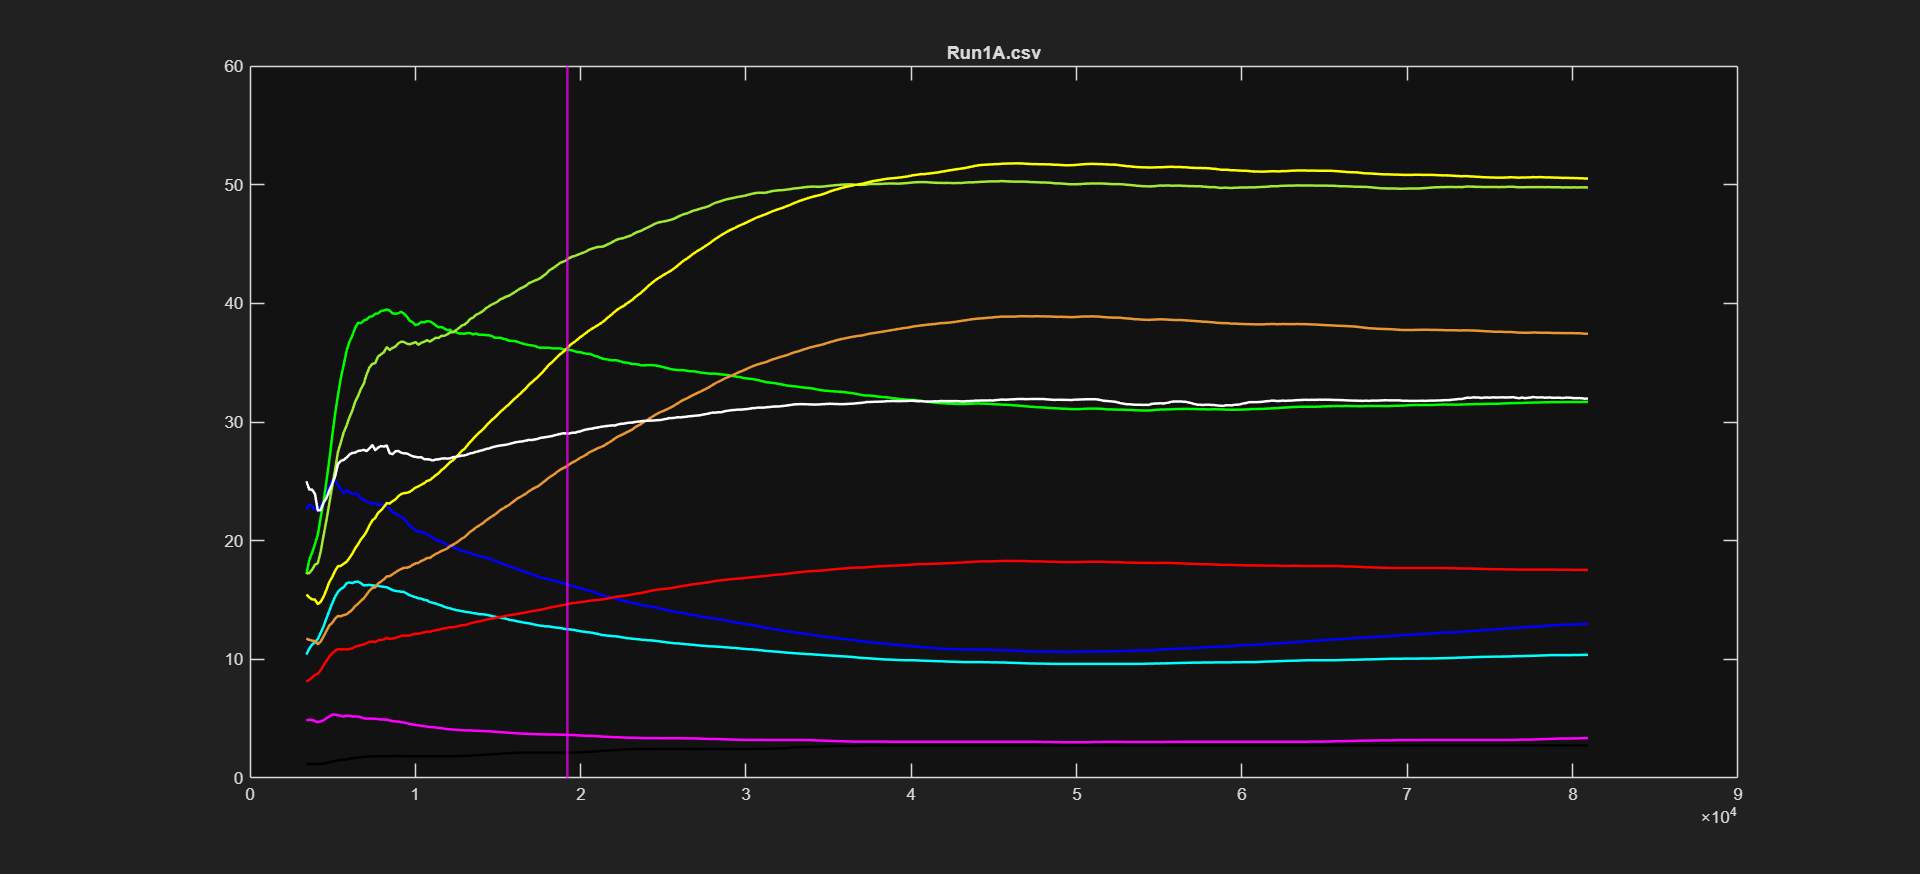

intervals = linspace(30134.5, 19196, 5);
RegimeMult = 20;

% makeplots("3A", 35000, 1 * RegimeMult)
% makeplots("3B", 35000, 2 * RegimeMult)
% makeplots("3C", 35000, 3 * RegimeMult)


makeplots("1A", intervals(5), 1 * RegimeMult)

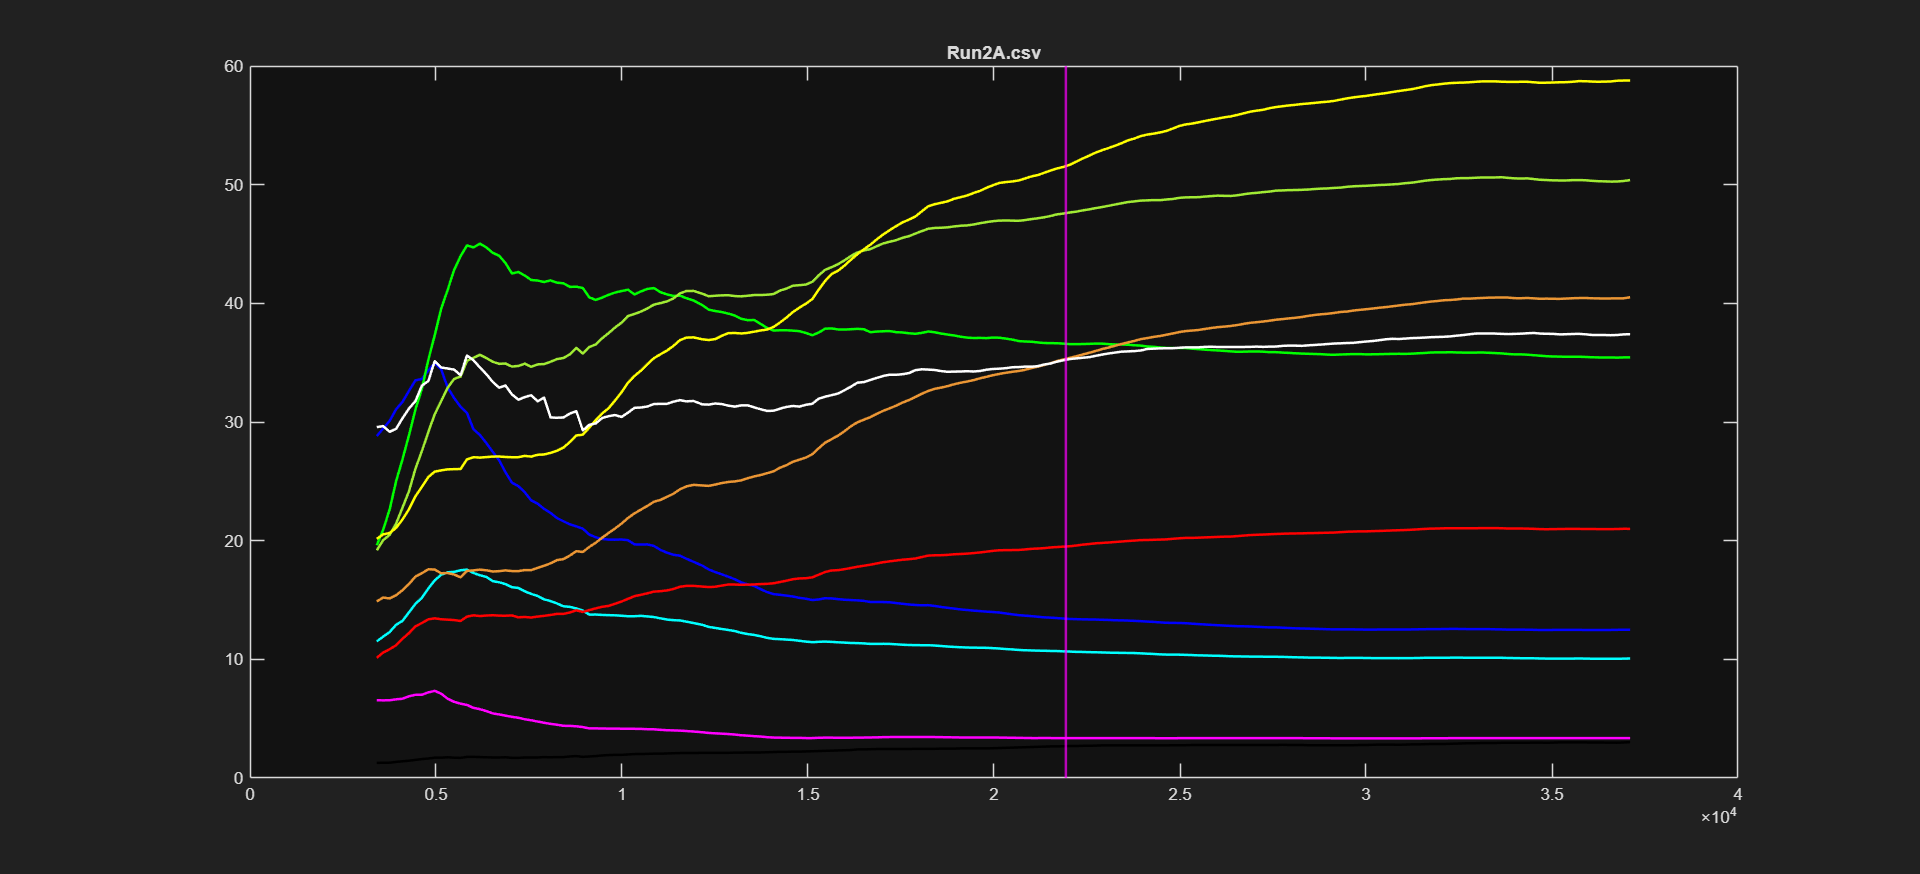

makeplots("2A", intervals(4), 1 * RegimeMult)

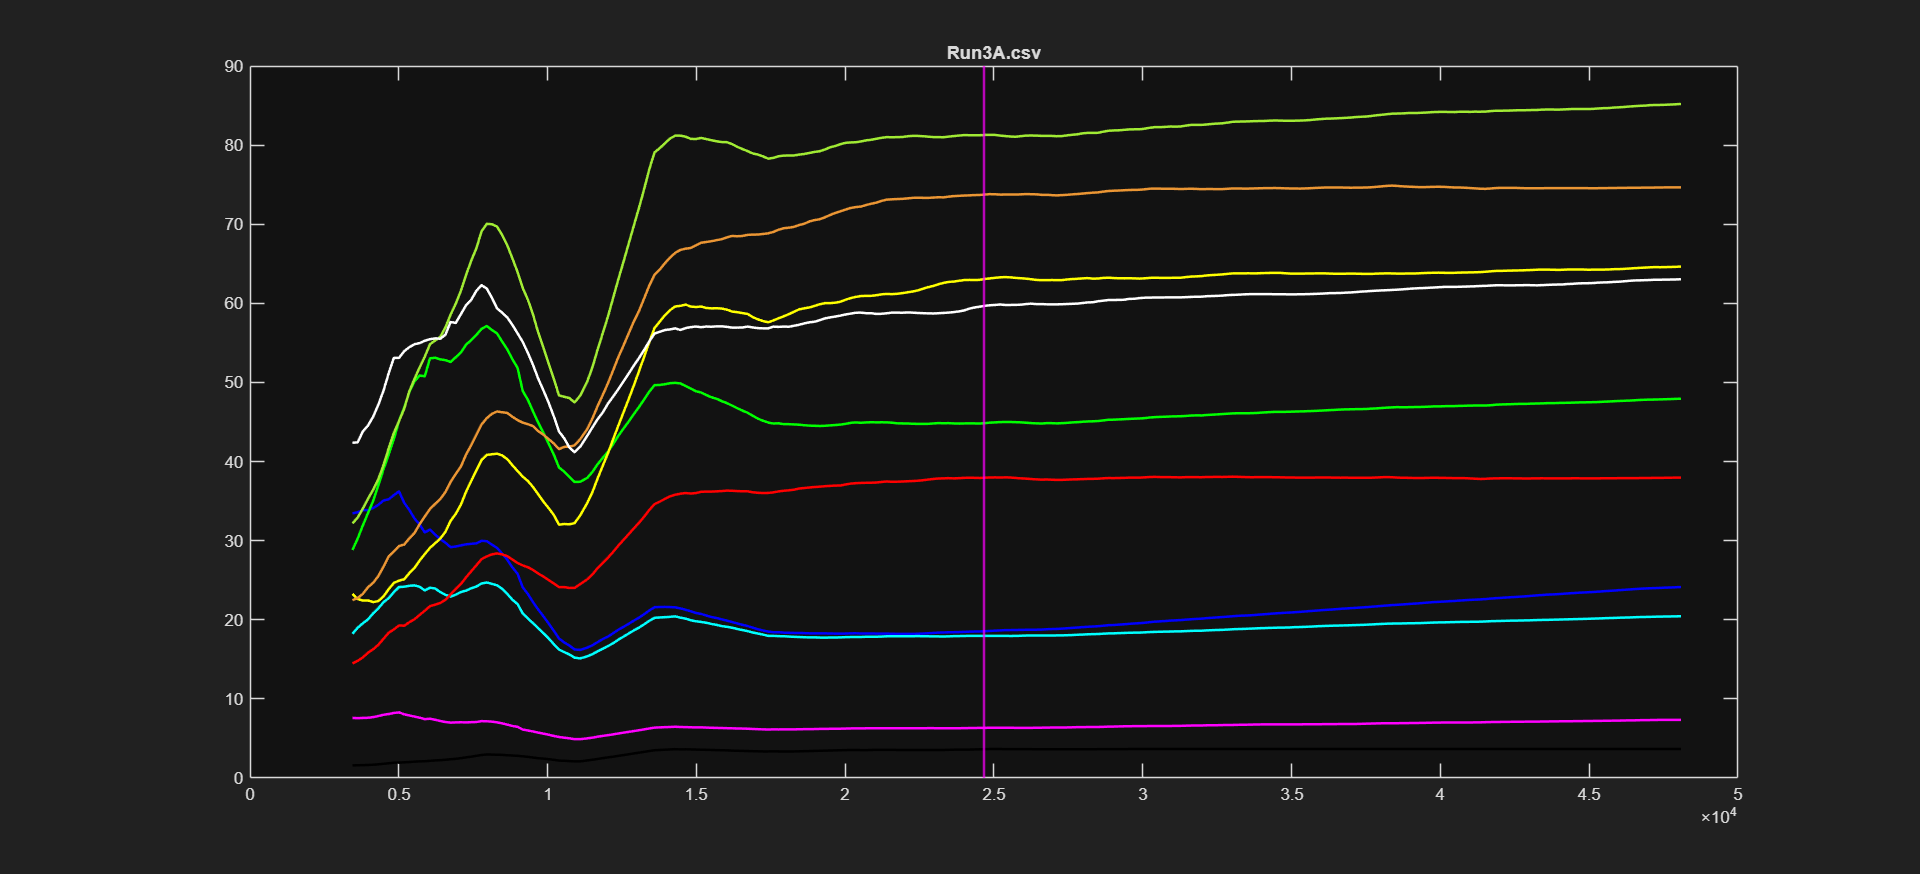

makeplots("3A", intervals(3), 1 * RegimeMult)

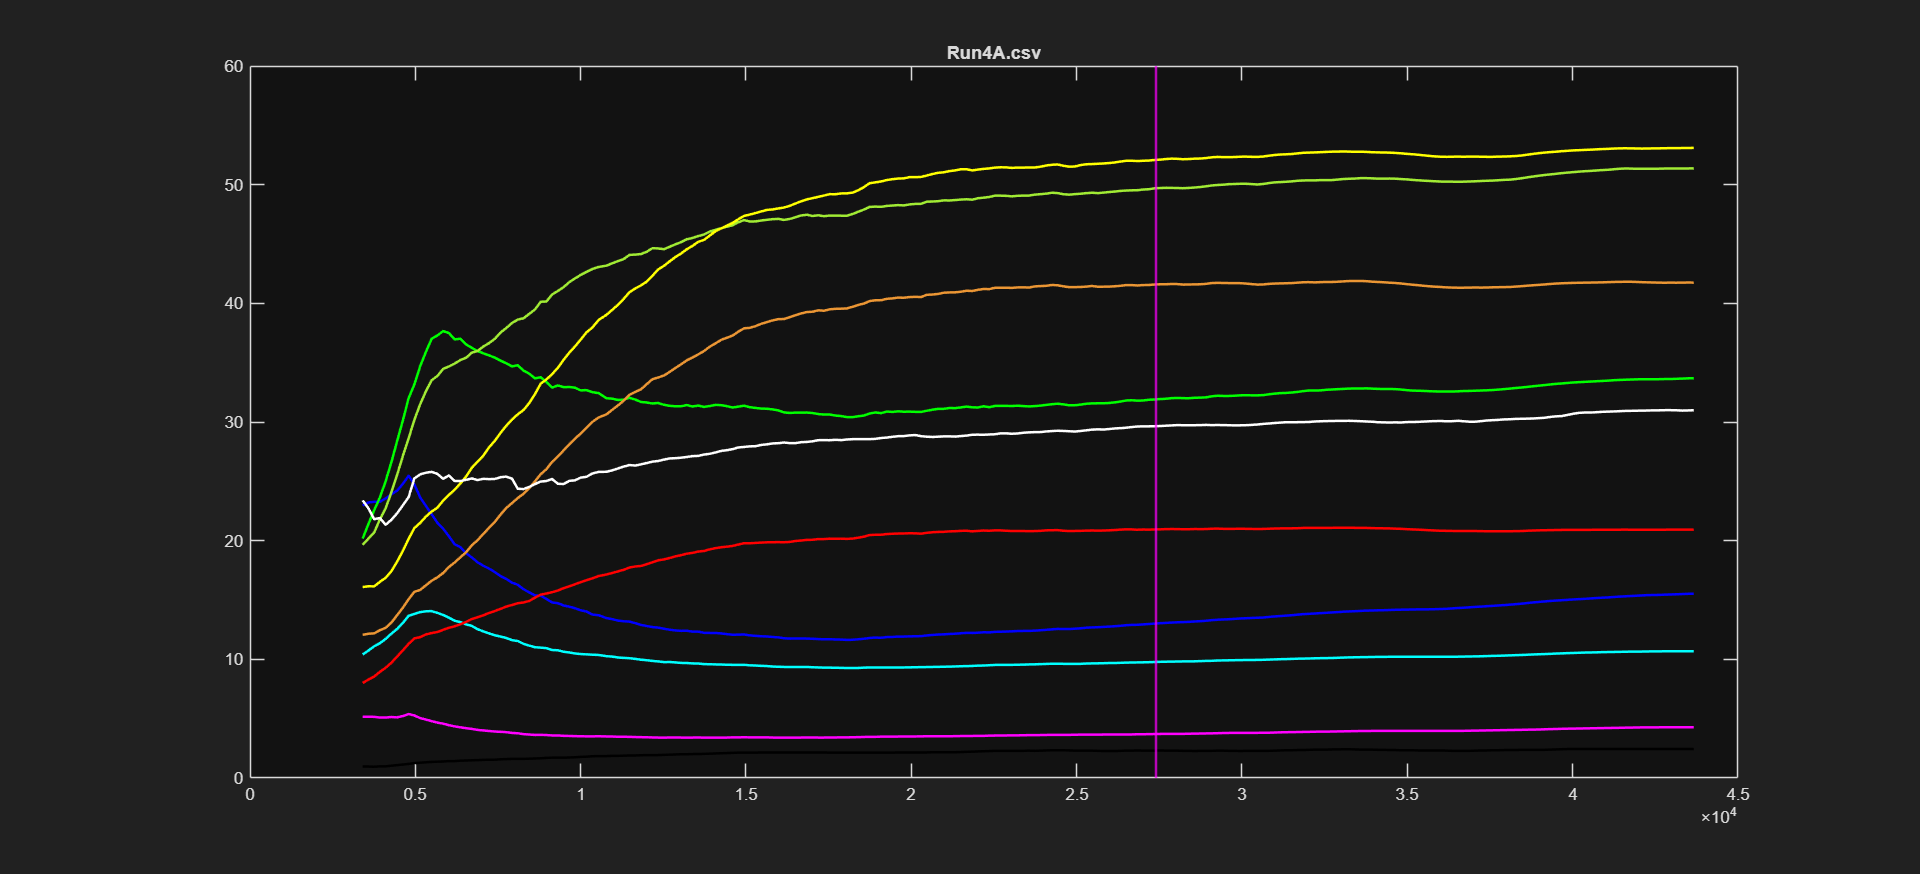

makeplots("4A", intervals(2), 1 * RegimeMult)

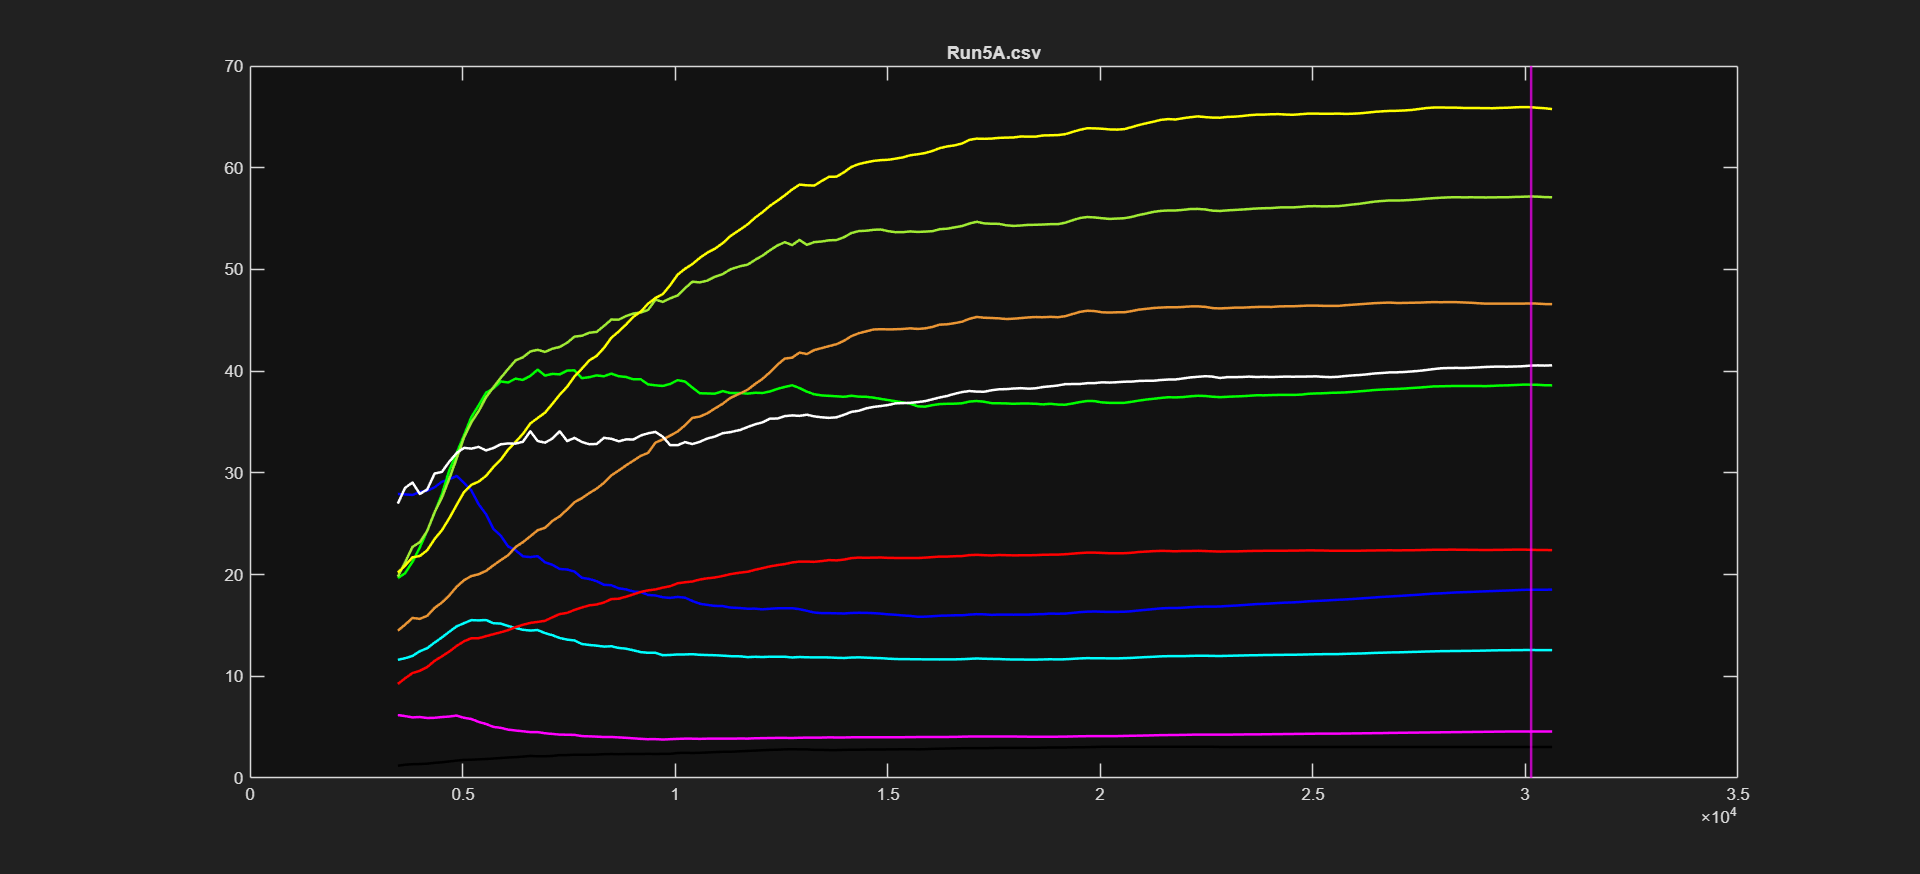

makeplots("5A", intervals(1), 1 * RegimeMult)

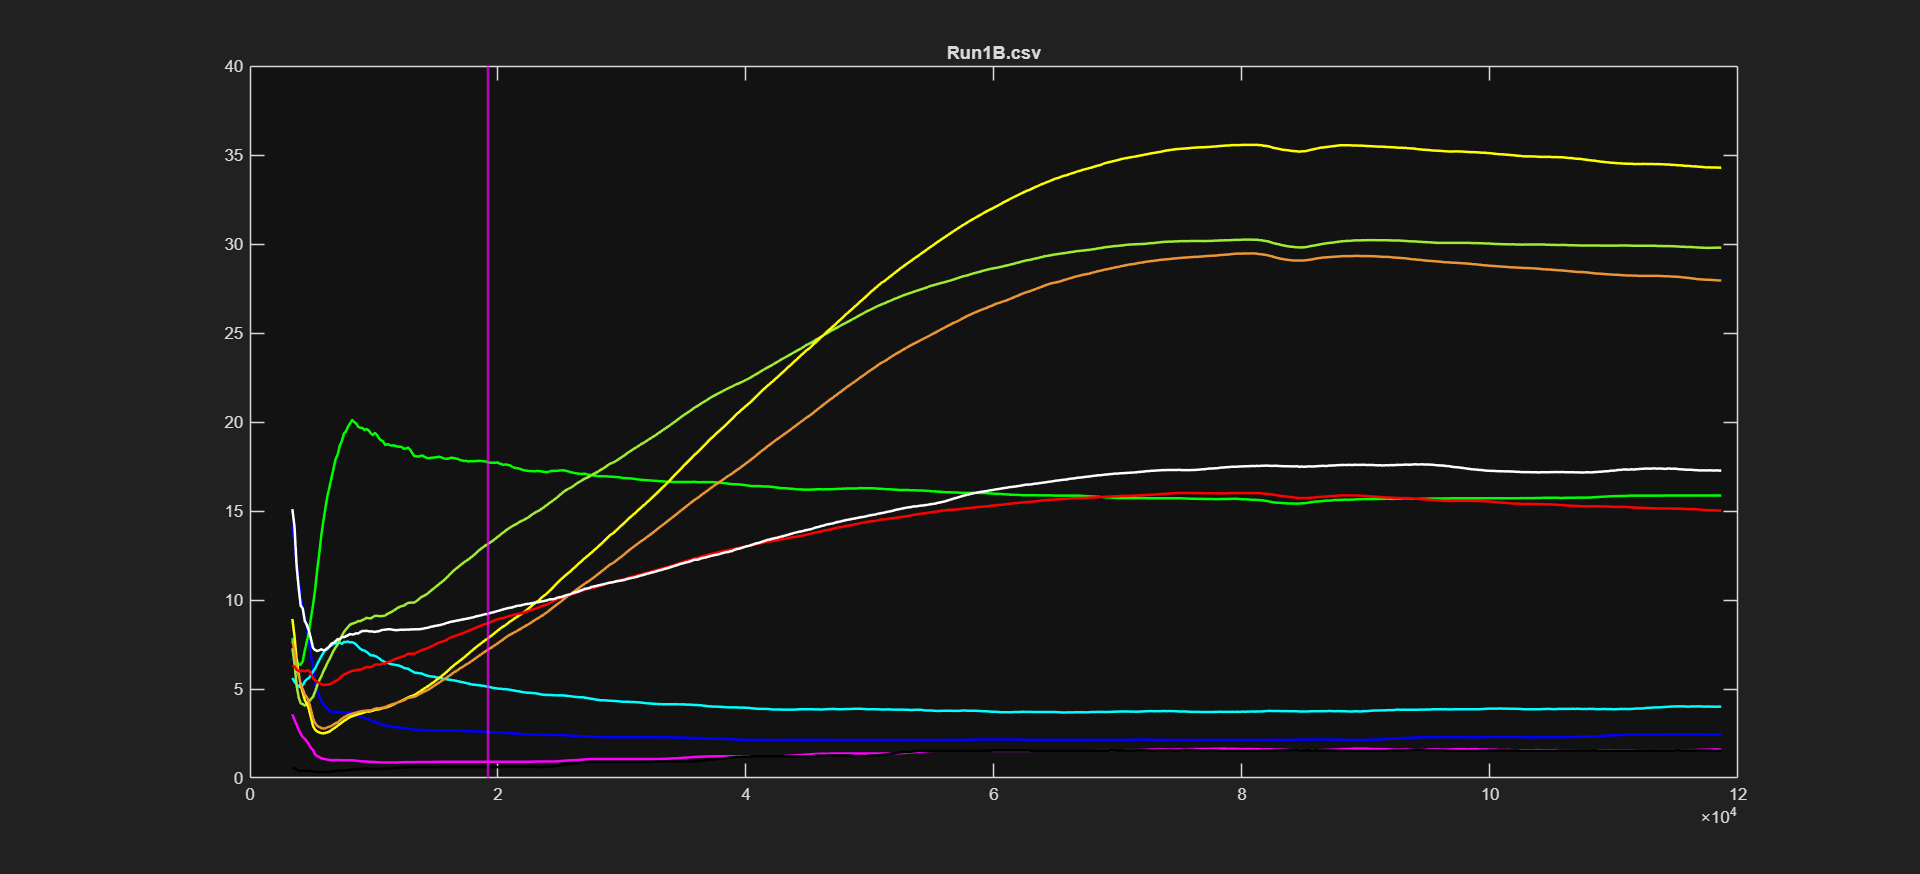


makeplots("1B", intervals(5), 2 * RegimeMult)

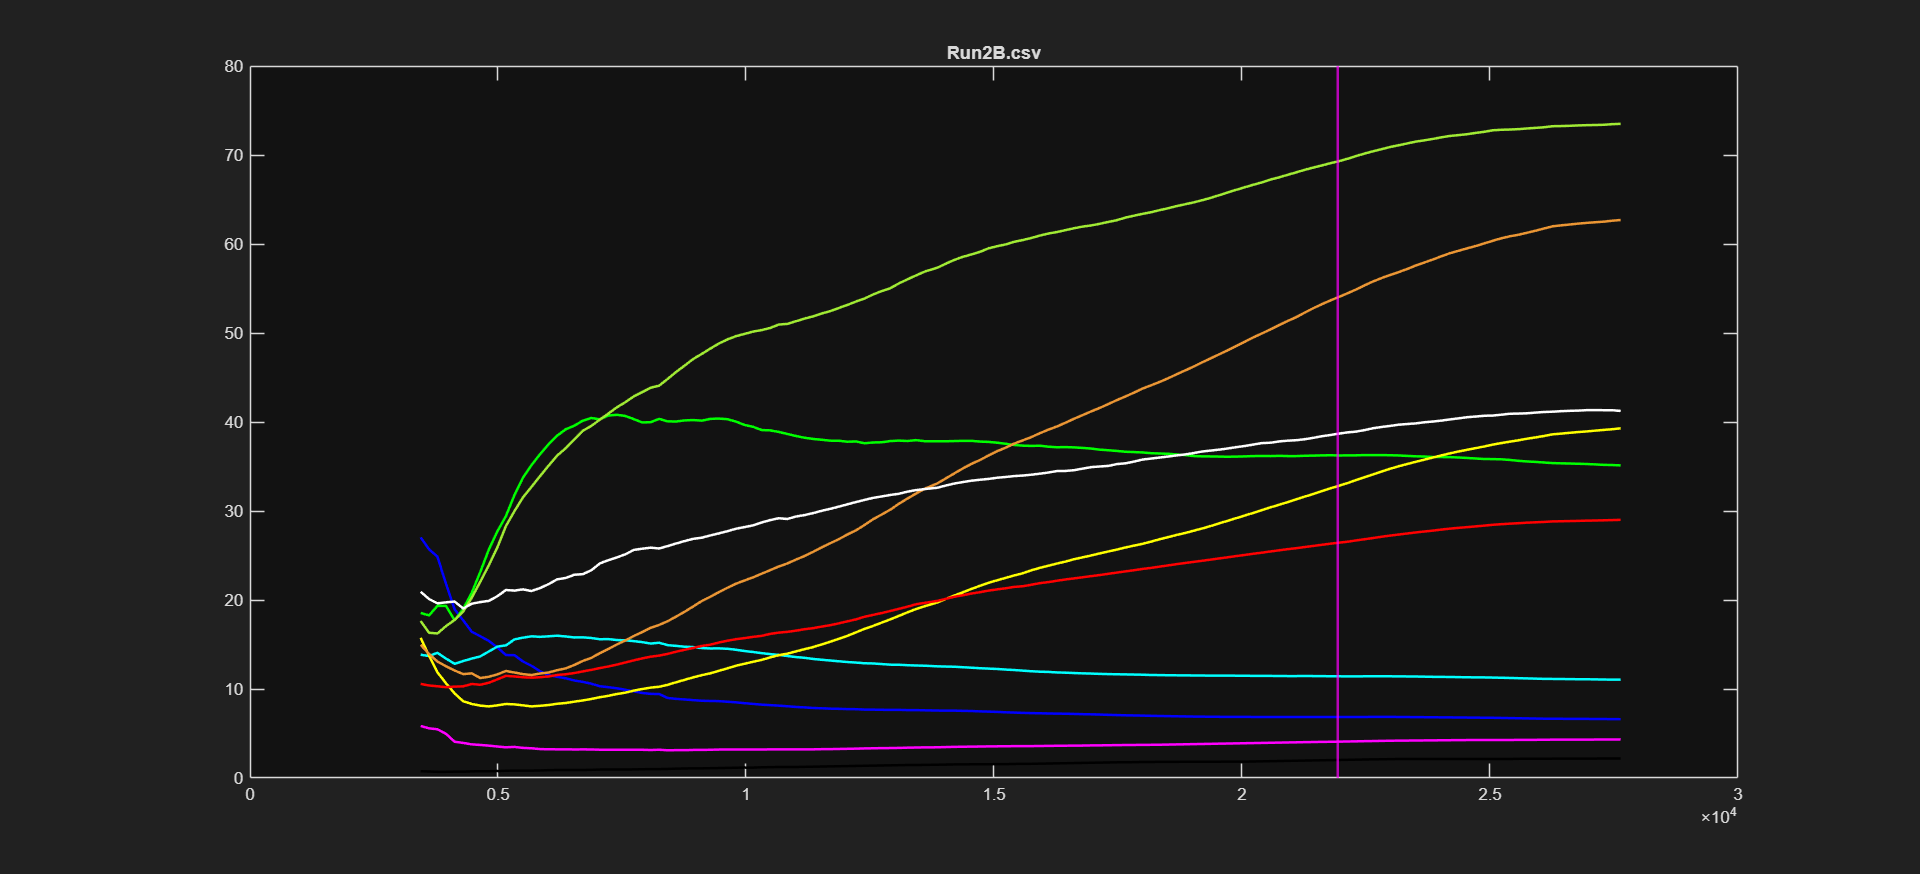

makeplots("2B", intervals(4), 2 * RegimeMult)

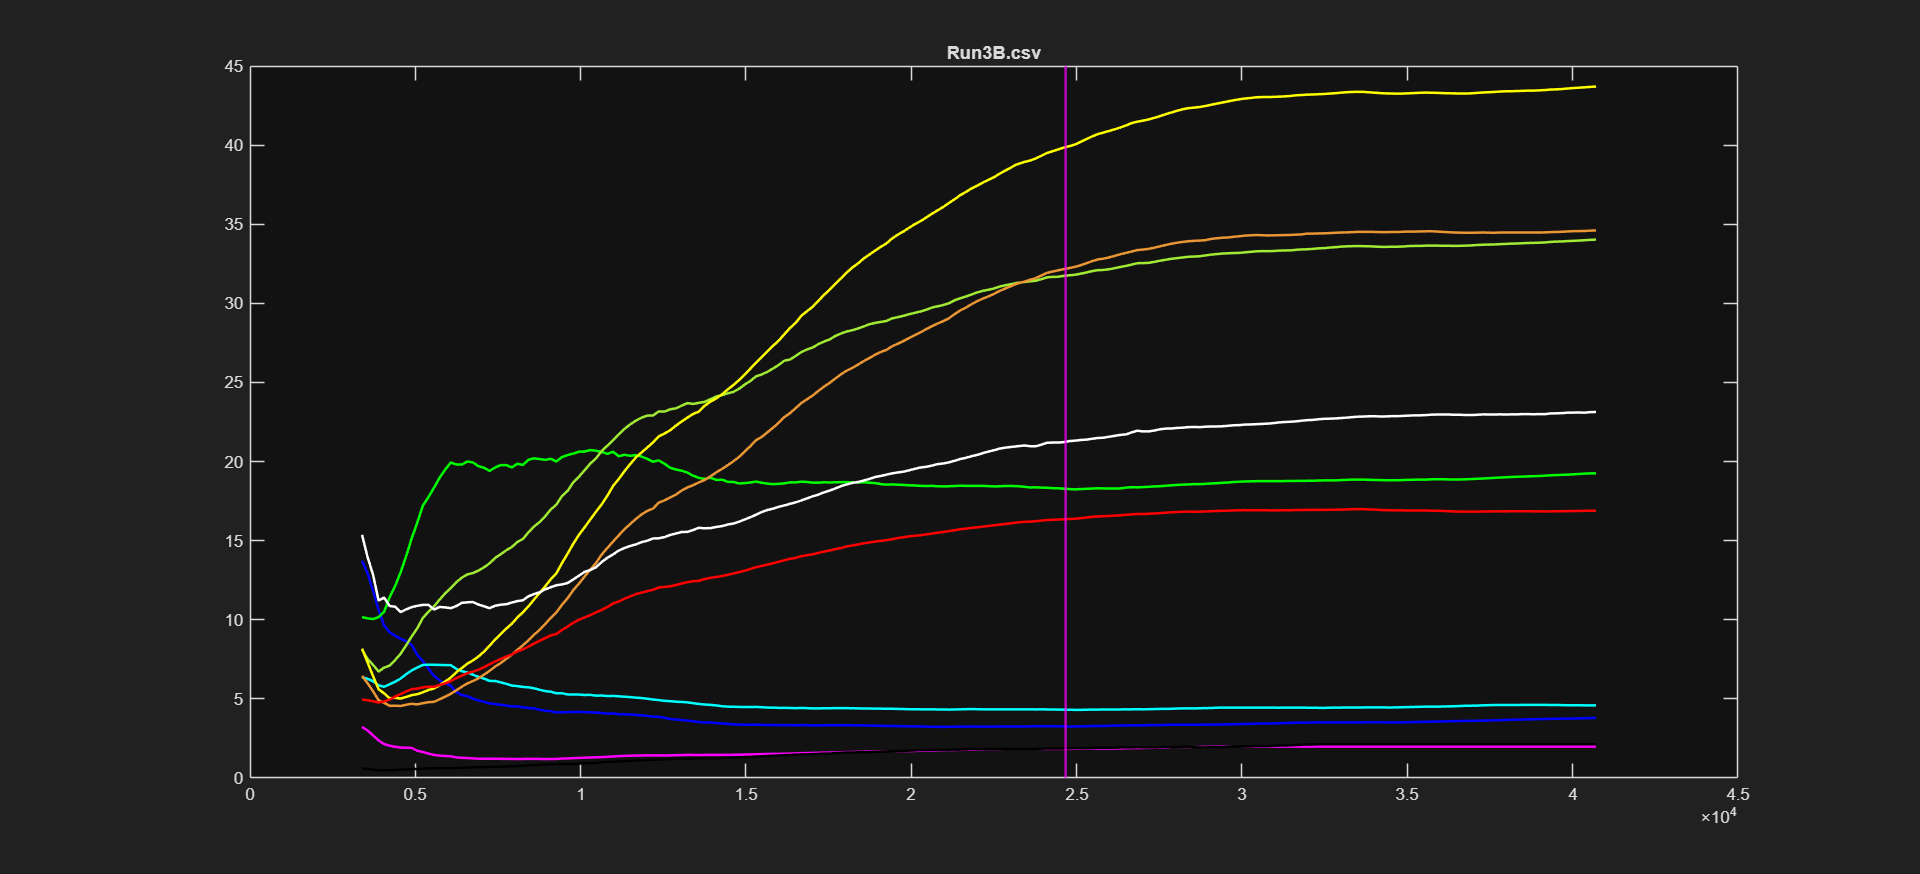

makeplots("3B", intervals(3), 2 * RegimeMult)

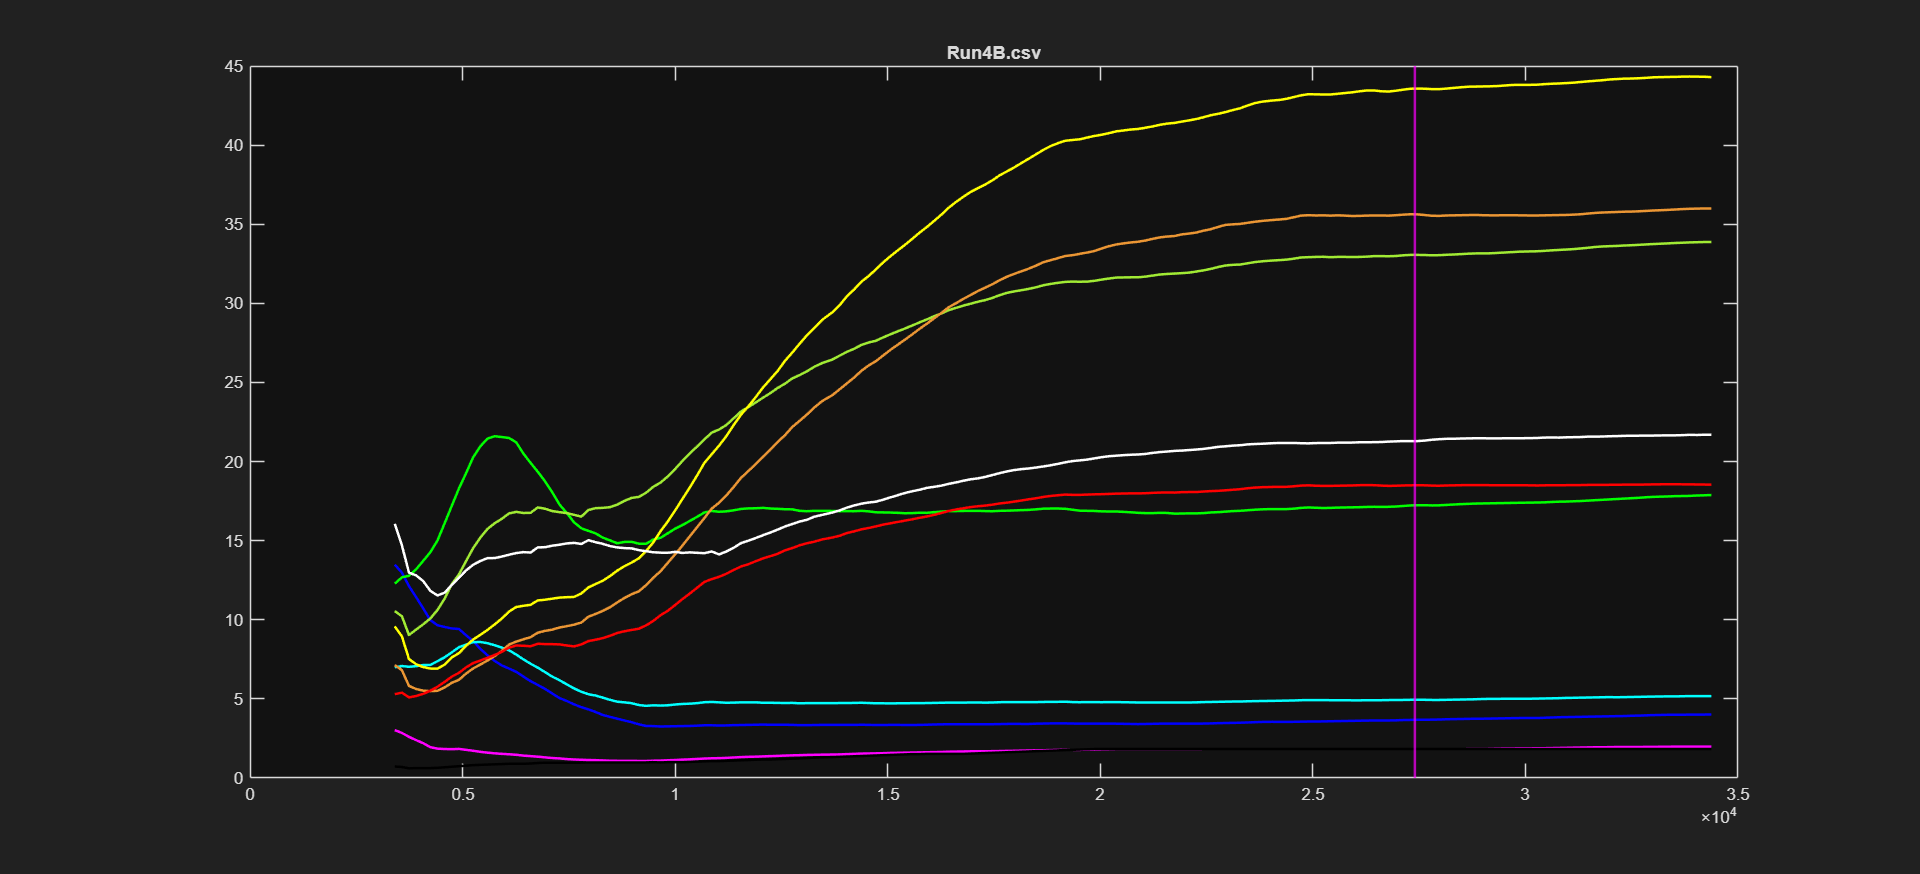

makeplots("4B", intervals(2), 2 * RegimeMult)

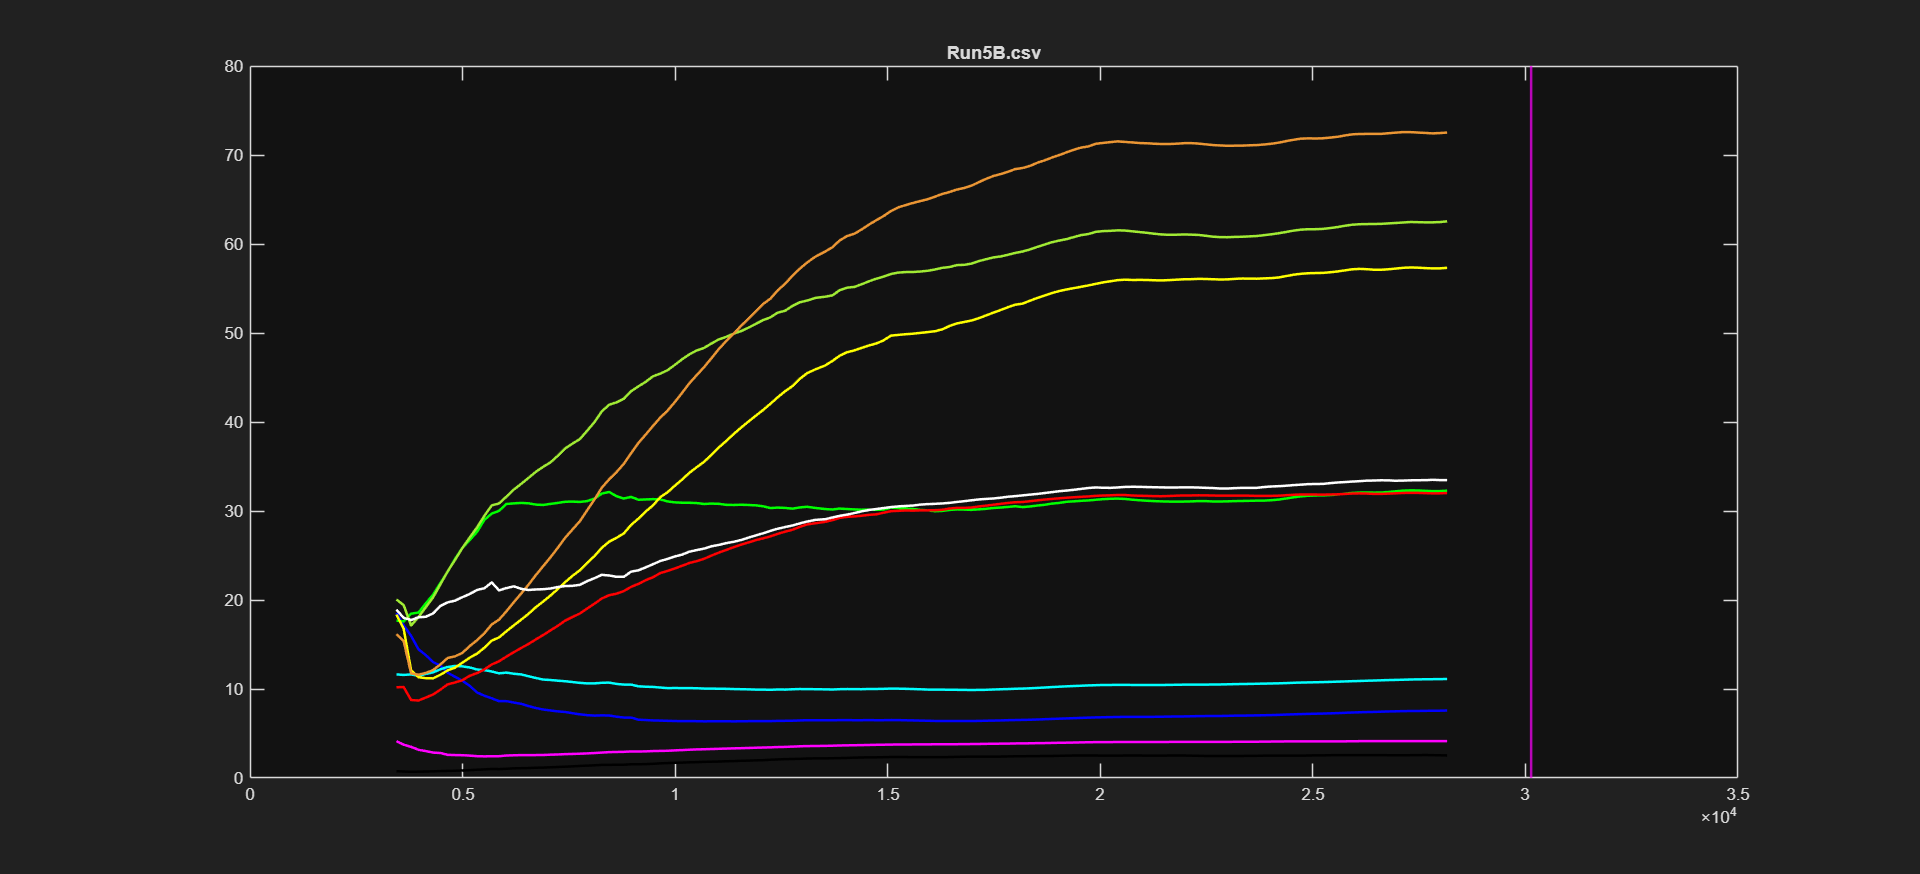

makeplots("5B", intervals(1), 2 * RegimeMult)

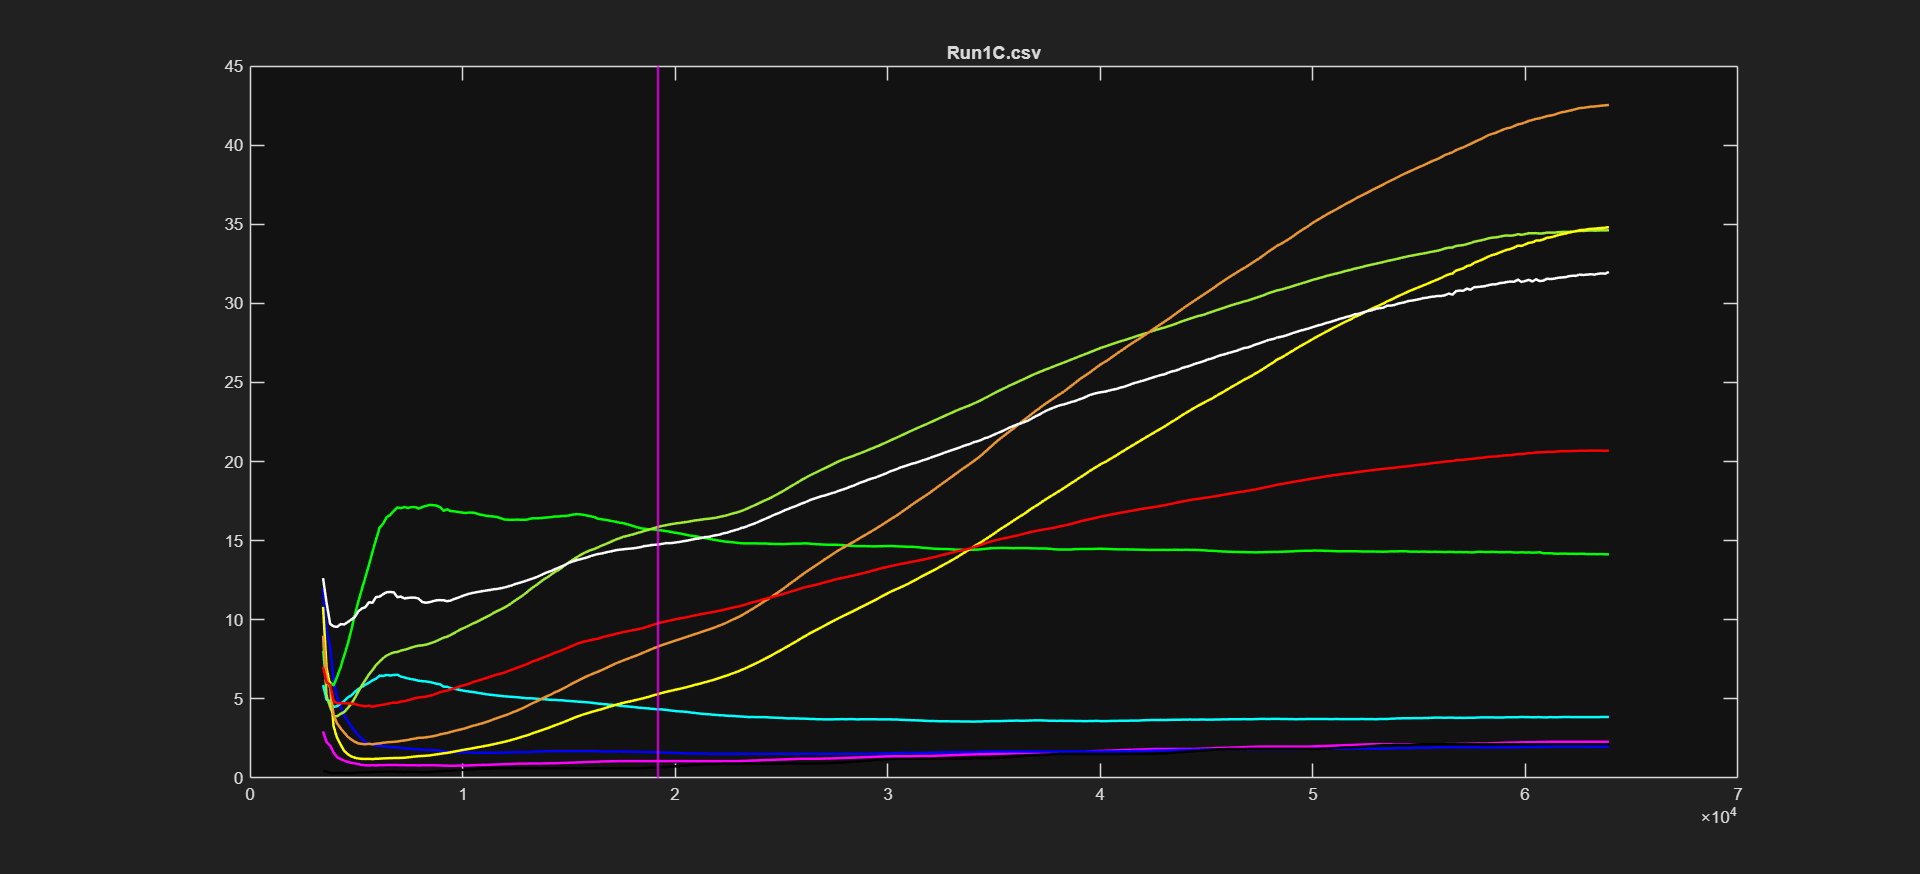


makeplots("1C", intervals(5), 3 * RegimeMult)

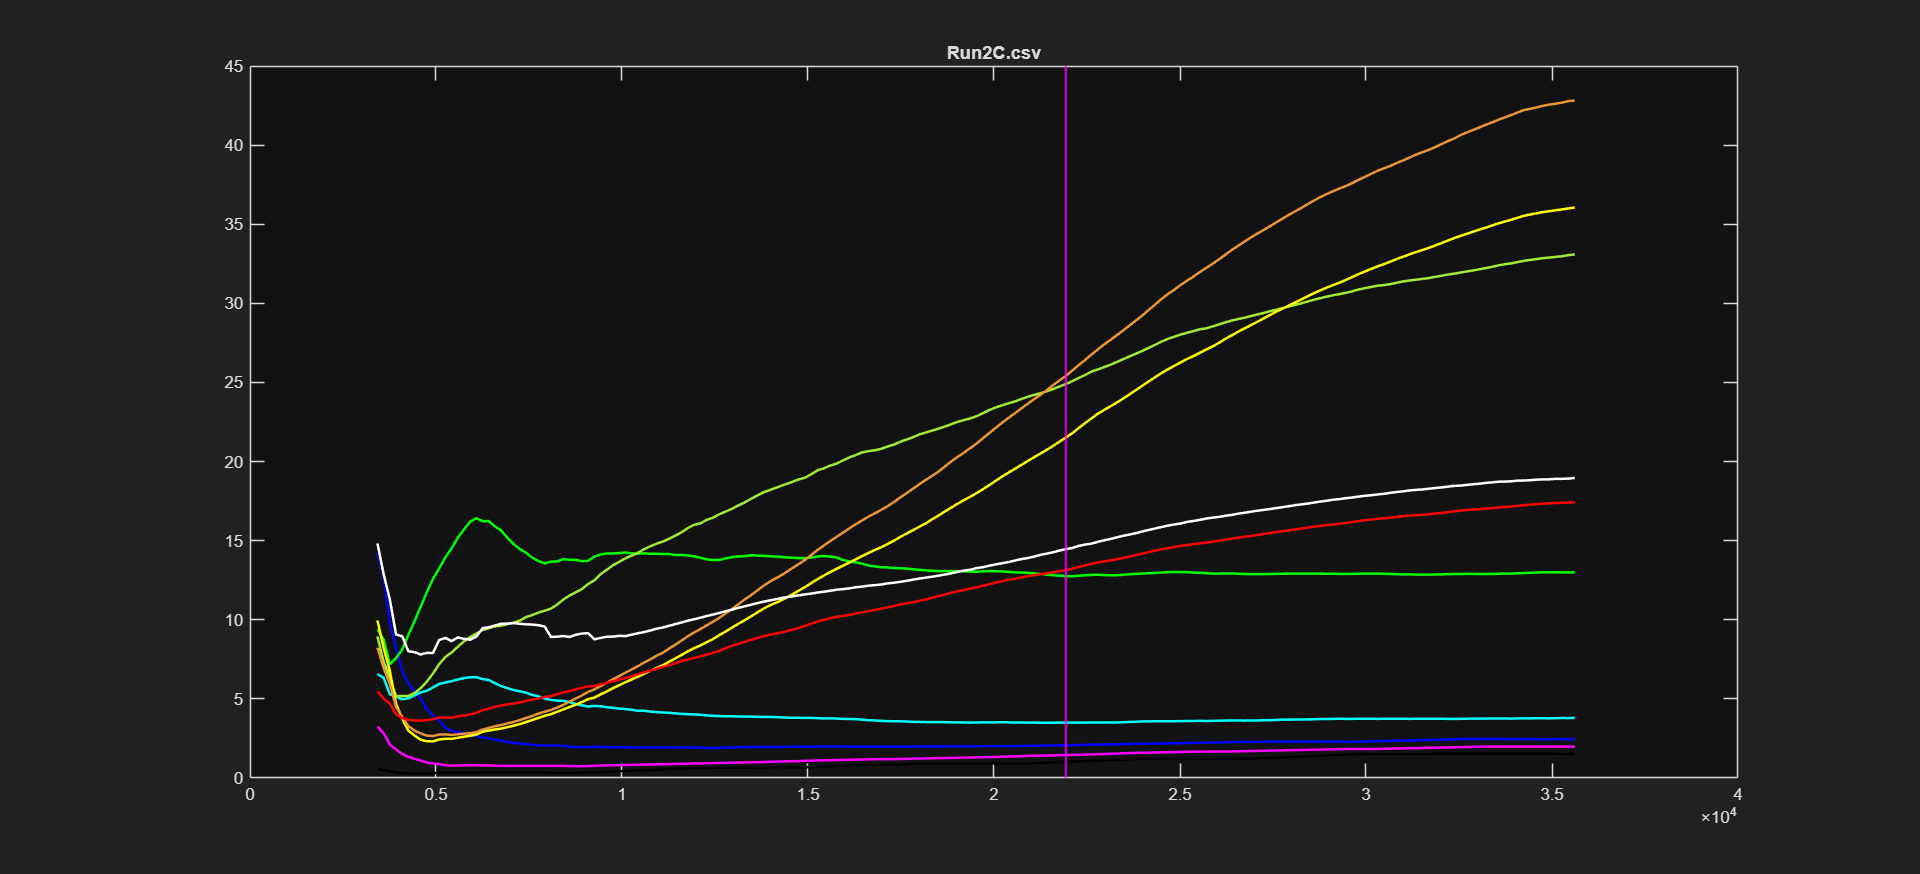

makeplots("2C", intervals(4), 3 * RegimeMult)

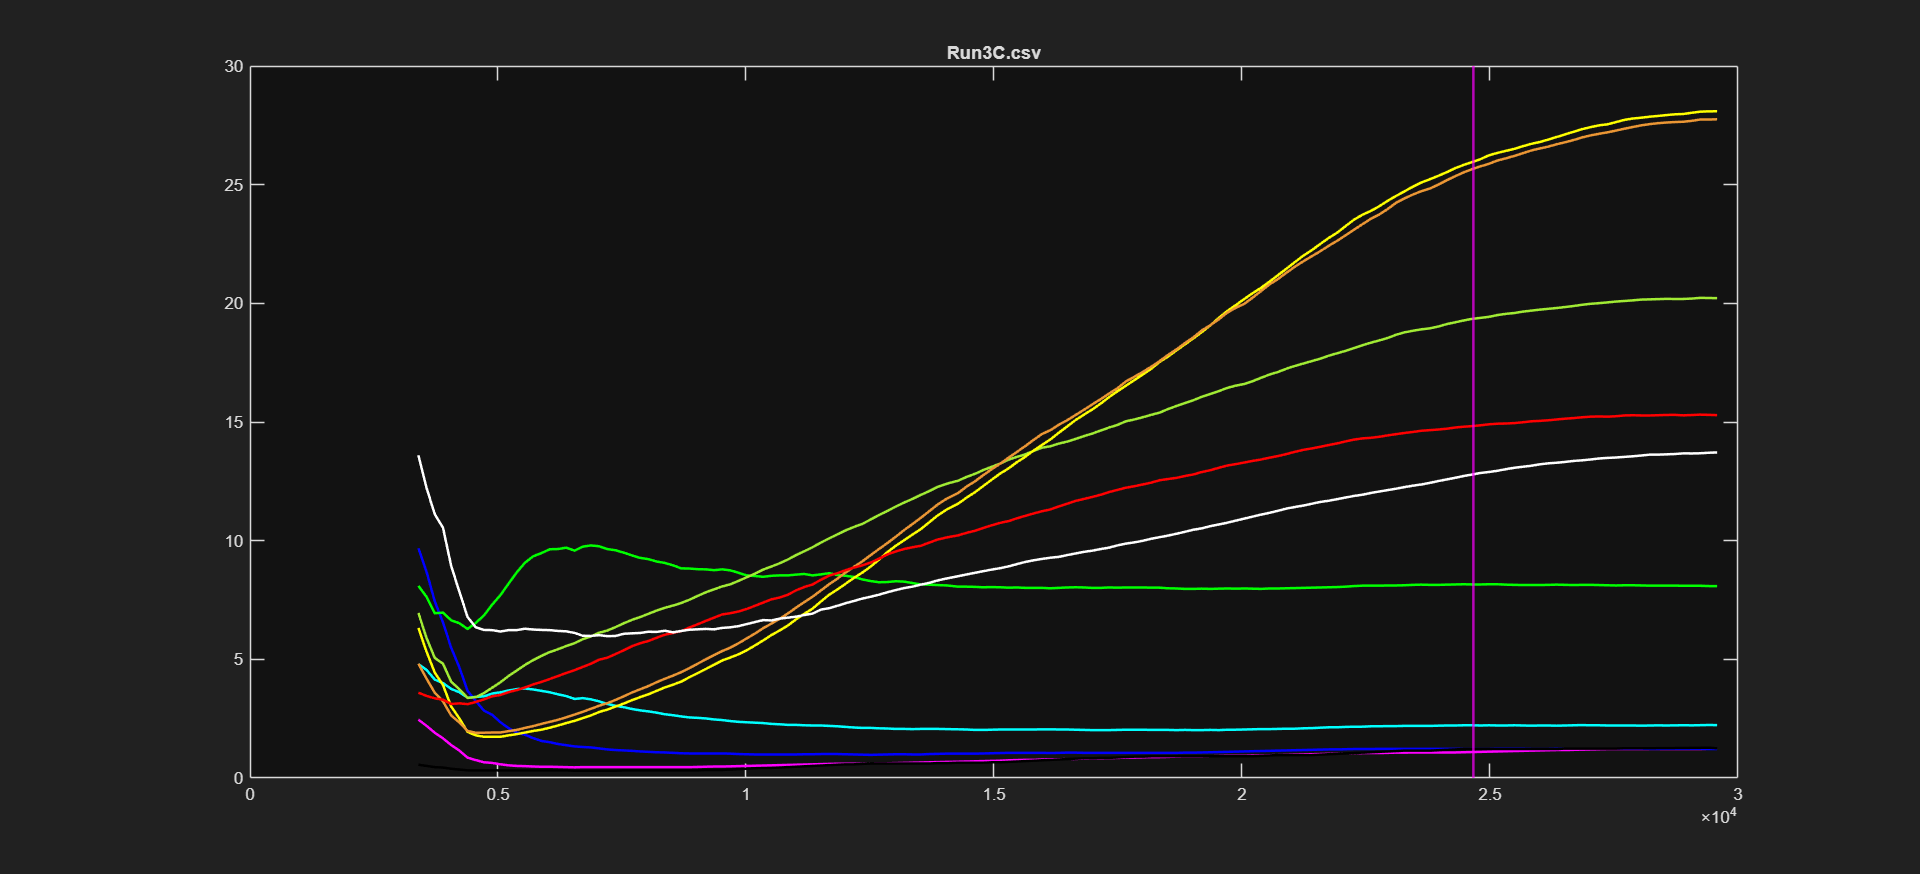

makeplots("3C", intervals(3), 3 * RegimeMult)

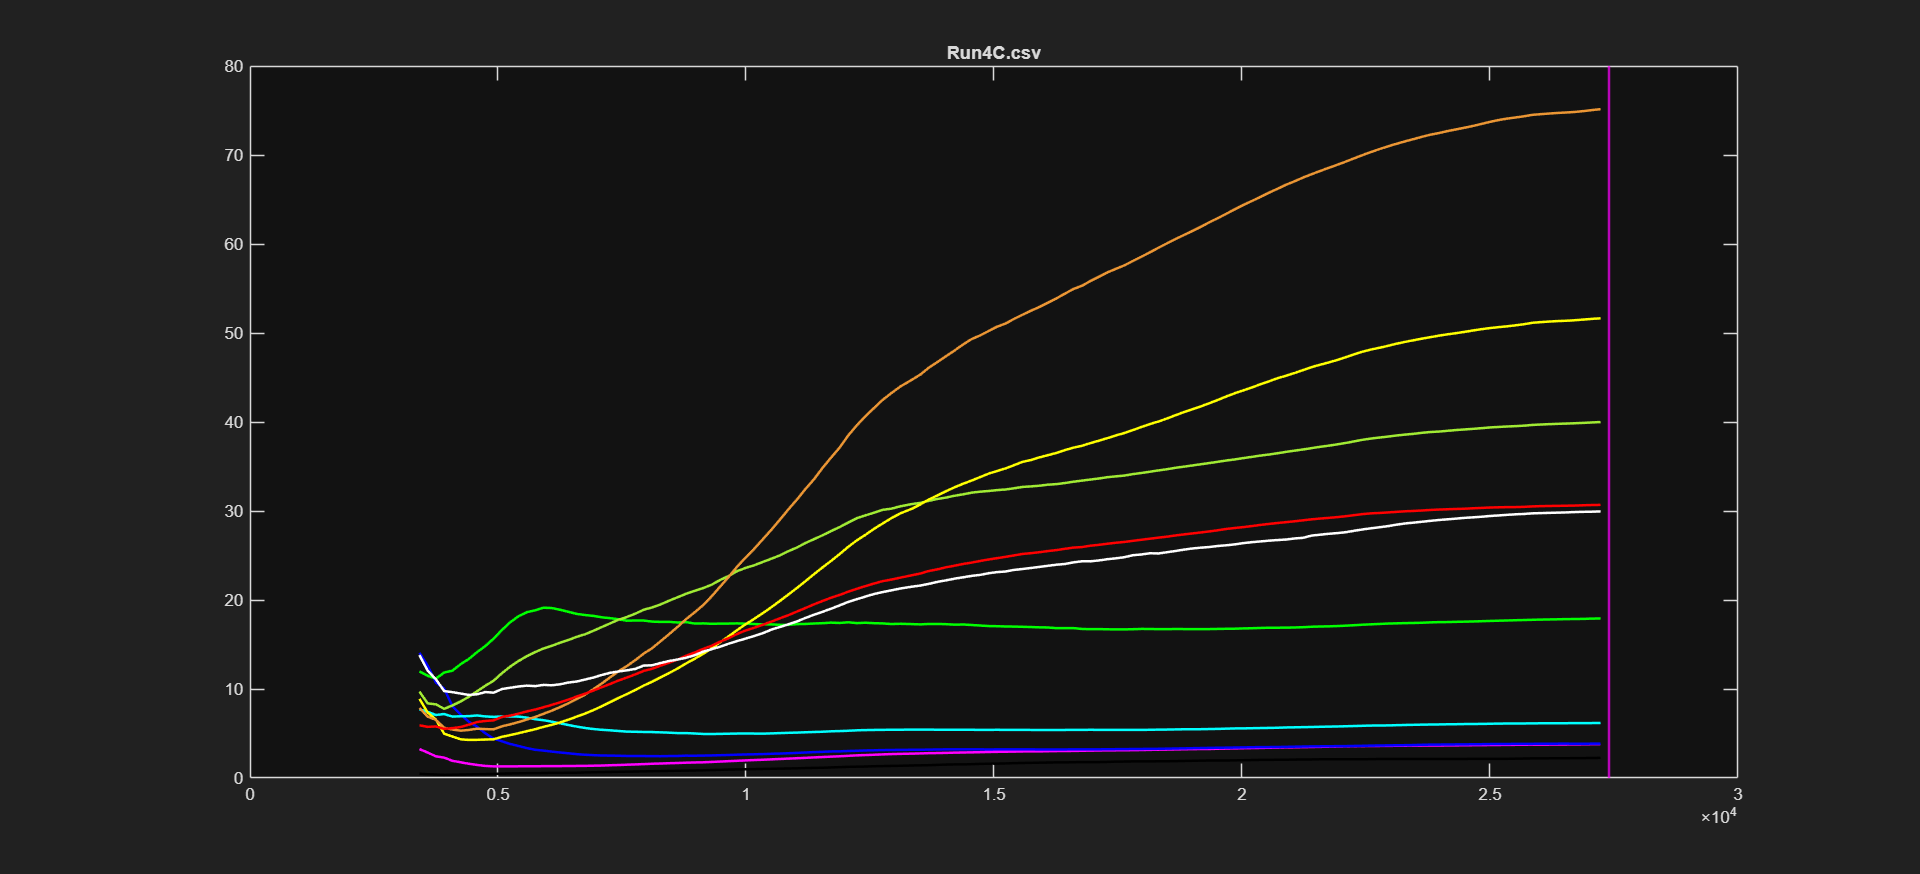

makeplots("4C", intervals(2), 3 * RegimeMult)

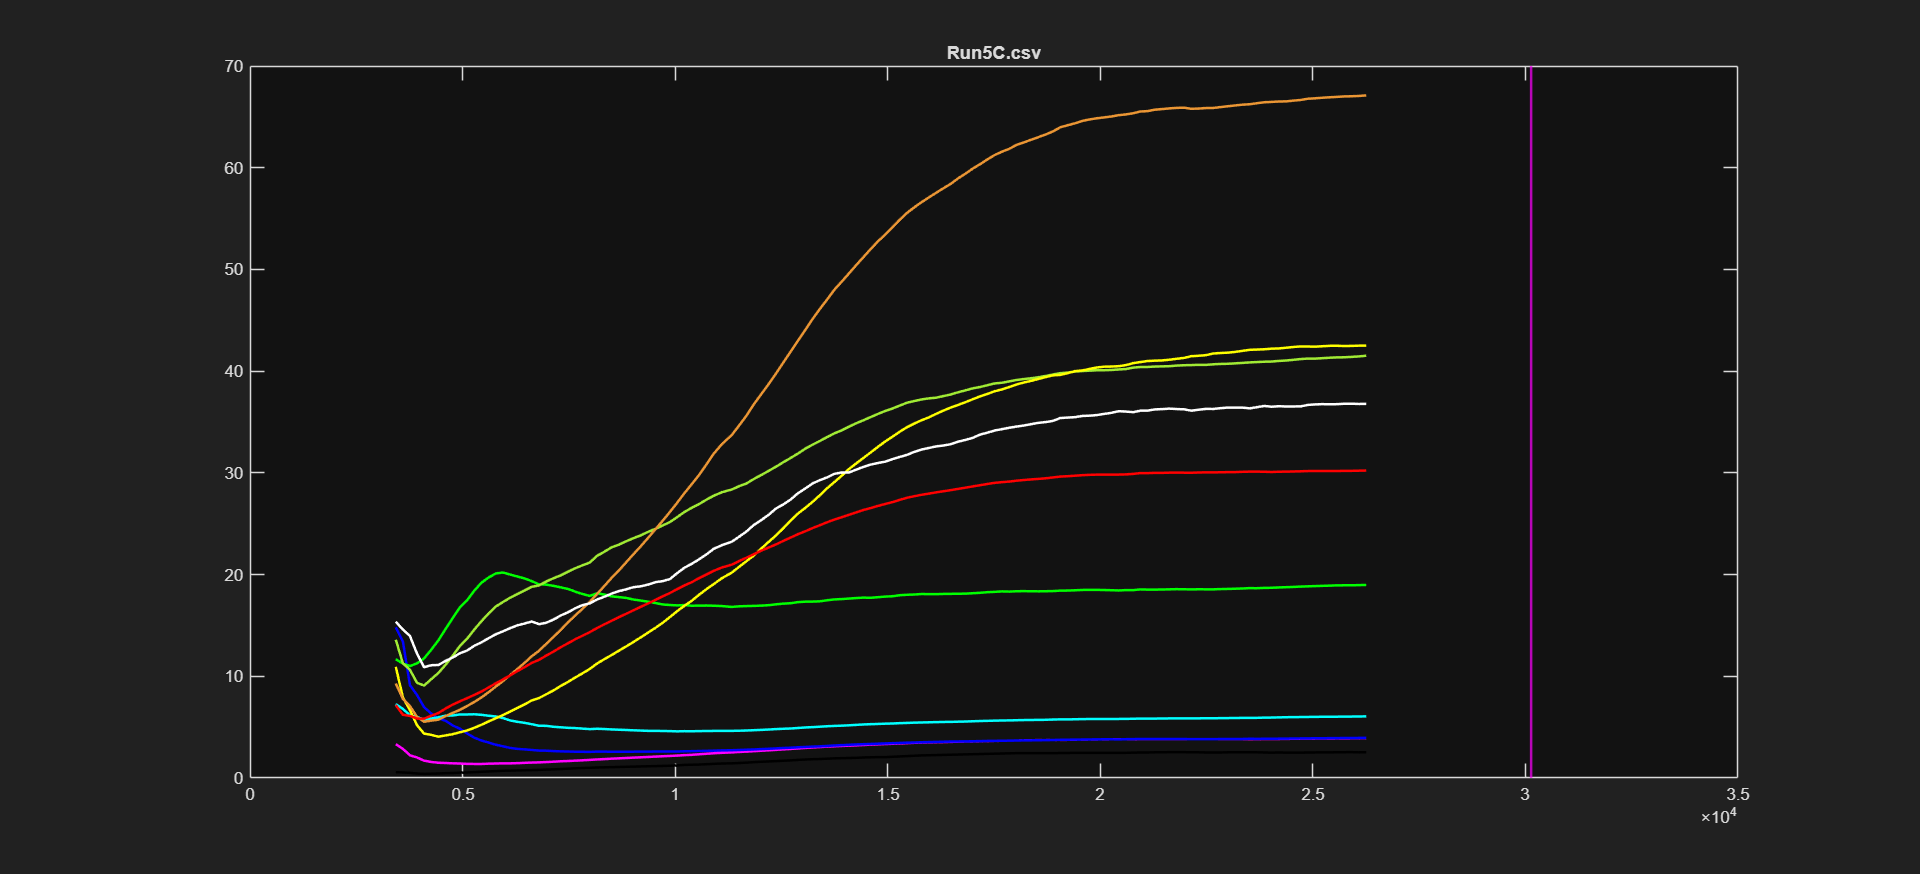

makeplots("5C", intervals(1), 3 * RegimeMult)


function makeplots(testNum, time, regime)
     fig = figure('Visible','on');   % or 'off' if you don't want windows popping up

    fileName = "Run" + testNum + ".csv";
    cd(fullfile("C:","Users","aryar","UM-ChemE-Car"));   % set to correct folder
    isfile("./chameleon_platformio/data/" + fileName);   % true if file exists
    
    opts = detectImportOptions("./chameleon_platformio/data/"+fileName,'Delimiter',','); % or set to correct delimiter
    opts.PreserveVariableNames = true;

    data = readtable("./chameleon_platformio/data/"+fileName, ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');
    
    

    
    myPlot(data.Time, data.v, "m");
    hold on
    myPlot(data.Time, data.b, "b");
    myPlot(data.Time, data.c, 'c');
    myPlot(data.Time, data.g, 'g');
    myPlot(data.Time, data.gy, [161 235 52]/255);
    myPlot(data.Time, data.y, 'y');
    myPlot(data.Time, data.o, [235 150 52]/255);
    myPlot(data.Time, data.r, 'r');
    myPlot(data.Time, data.cl, 'w');
    myPlot(data.Time, data.nir, [0 0 0]);
    xline(time, 'LineWidth', 1.5, 'Color', [1,0,1]);
    % yline(regime, 'LineWidth', 1.5, 'Color', [1,0,1]);
    hold off
    title(fileName);

    % exportgraphics(fig, fileName + ".png", "Resolution", 300);
    %close(fig);   % optional, closes the figure after saving
end


function myPlot(time, input, color)
    cutoffValue = 20;
    smoothed = movmean(input, 18);

    plot(time(cutoffValue:end), smoothed(cutoffValue:end), ...
        'Color', color, 'LineWidth', 1.5);
end


